clear; close all; clc

%Import data:
didymo = importdata('didymo.obj');
dimorphus = importdata('dimorphos.obj');

%Extract index information for both verticies and faces for both
didymo_v_indices = find(strcmp(didymo.textdata, 'v'));
didymo_f_indices = find(strcmp(didymo.textdata, 'f'));

dimorphus_v_indices = find(strcmp(dimorphus.textdata, 'v'));
dimorphus_f_indices = find(strcmp(dimorphus.textdata, 'f'));

%Extract coordinatates, face and distance information for a coloursheme
didymo_coords = didymo.data(didymo_v_indices, :).*1000; %Convert to meters 
didymo_faces = didymo.data(didymo_f_indices,:);
didymo_distances = vecnorm(didymo_coords, 2, 2);

dimorphus_coords = dimorphus.data(dimorphus_v_indices, :).*1000; %Convert to meters 
dimorphus_faces = dimorphus.data(dimorphus_f_indices,:);
dimorphus_distances = vecnorm(dimorphus_coords, 2, 2);

dimorphus_coords(:,1) = dimorphus_coords(:,1)+1180;%Nudge dimorphus over that far as thats the seperation between the two
%Probably surface to surface however so this isnt accurate.

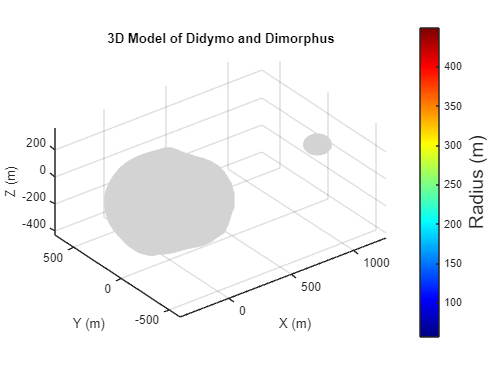

figure;
patch('Vertices', didymo_coords,'Faces', didymo_faces,'FaceVertexCData',didymo_distances,'FaceColor','interp','EdgeColor', '#D3D3D3');
patch('Vertices', dimorphus_coords,'Faces', dimorphus_faces,'FaceVertexCData',dimorphus_distances,'FaceColor','interp','EdgeColor', '#D3D3D3');
colormap(jet);
axis equal % makes the axes scales equal
grid on % turns on the grid
xlabel('X (m)'); % labels the x-axis
ylabel('Y (m)'); % labels the y-axis
zlabel('Z (m)'); % labels the z-axis
title('3D Model of Didymo and Dimorphus') % adds a title to the plot
colorbar; % adds the colorbar
ylabel(colorbar, 'Radius (m)','FontSize', 16); % labels the colorbar
view(3); % sets the default 3D view

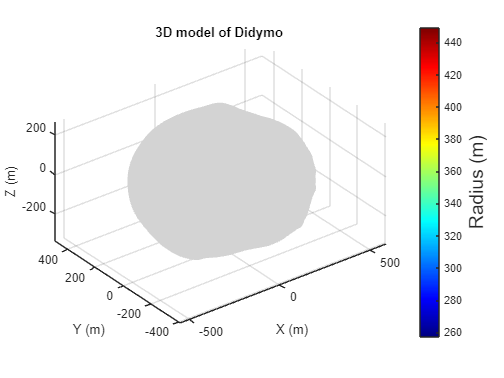

figure;
patch('Vertices', didymo_coords,'Faces', didymo_faces,'FaceVertexCData',didymo_distances,'FaceColor','interp','EdgeColor','	#D3D3D3');
colormap(jet);
axis equal % makes the axes scales equal
grid on % turns on the grid
xlabel('X (m)'); % labels the x-axis
ylabel('Y (m)'); % labels the y-axis
zlabel('Z (m)'); % labels the z-axis
title('3D model of Didymo ') % adds a title to the plot
colorbar; % adds the colorbar
ylabel(colorbar, 'Radius (m)','FontSize', 16); % labels the colorbar
view(3); % sets the default 3D view

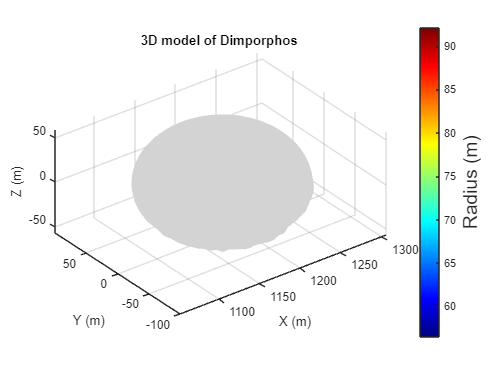

figure;
patch('Vertices', dimorphus_coords,'Faces', dimorphus_faces,'FaceVertexCData',dimorphus_distances,'FaceColor','interp','EdgeColor','	#D3D3D3');
colormap(jet);
axis equal % makes the axes scales equal
grid on % turns on the grid
xlabel('X (m)'); % labels the x-axis
ylabel('Y (m)'); % labels the y-axis
zlabel('Z (m)'); % labels the z-axis
title('3D model of Dimporphos ') % adds a title to the plot
colorbar; % adds the colorbar
ylabel(colorbar, 'Radius (m)','FontSize', 16); % labels the colorbar
view(3); % sets the default 3D view